# Degredation Parameter Extraction

## Loop over cycles & stores data within mat file


battery = "MOLI_28\";

### Below is iclocs purley from voltage output


batches = Batch_Setup("MOLI_28\",0,1);
for i = 1:length(batches)
[problem,guess]=BatteryEstimation(batches(i));         
options= problem.settings(130);                  
[solution_unbound,~]=solveMyProblem( problem,guess,options);
save(batches(i),"solution_unbound","-append")
clear solution
end

ans = 'C:\Users\jekir\GitHub\FYP_Battery\Matlab\Learning\Dans_Data_Extraction'

Determine sparsity structure
Formatting matrices for the hermite-simpson approximation
Generate finite-difference pertubation vectors
This is Ipopt version 3.14.4, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:     9546
Number of nonzeros in Lagrangian Hessian.............:     9154

Total number of variables............................:      531
                     variables with only lower bounds:        0
                variables with lower and upper bounds:      531
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:      518
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:      518
        inequality constraints with only upper bounds:        0

iter    objective    inf_

Error using save
Argument must be a text scalar.

### Below is iclocs with temperature fitting (weighting mse can be adjusted)


batches = Batch_Setup("MOLI_28\",1,1);
for i = 1:length(batches)
filename = string(batches(i));  
data = load(filename);
    if isfield(data, "tp")
        tp_val = data.tp;
        if any(isnan(tp_val), 'all')
            continue 
        end
    else
        continue
    end
[problem,guess]=BatteryEstimation_temp(batches(i));         
options= problem.settings(130);                  
[solution_temp,~]=solveMyProblem( problem,guess,options);
save(batches(i),"solution_temp","-append")
clear solution
end

ans = 'C:\Users\jekir\GitHub\FYP_Battery\Matlab\Learning\Dans_Data_Extraction'

Determine sparsity structure
Formatting matrices for the hermite-simpson approximation
Generate finite-difference pertubation vectors
This is Ipopt version 3.14.4, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:    17802
Number of nonzeros in Lagrangian Hessian.............:    16821

Total number of variables............................:      792
                     variables with only lower bounds:        0
                variables with lower and upper bounds:      792
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:      777
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:      777
        inequality constraints with only upper bounds:        0

iter    objective    inf_

### Below is greyest irreversable, based of iclocs v_out fitting only

current_lut = @(t) interp1(tt, u1, t, 'linear', 'extrap');
yactual_lut = @(t) interp1(tt, y, t, 'linear', 'extrap');
[t_sim, y_sim] = ode45(@(t, y) dynamics(t, y, p, current_lut), [0 tt(end)], [1; 0.05]);
x1=y_sim(:,1);x2=y_sim(:,2); R0 = p(end-1);
u2=current_lut(t_sim);
polyss = flip(p(1:end-4));
OCV_x = polyval(polyss,x1);
voltage_model=OCV_x + x2 + R0.*u2;
Q_heat = (voltage_model - OCV_x).*current_lut(t_sim);
Q_lut = @(tn) interp1(t_sim, Q_heat, tn, 'linear', 'extrap');
temp_lut = @(tn) interp1(tt, tp, tn, 'linear', 'extrap');

greyest_time_sampling = linspace(t_sim(1),t_sim(end),1500);

% Sample the heat generation data for the specified time points
U_sampled = Q_lut(greyest_time_sampling);
%Current_sampled = current_lut(greyest_time_sampling);
Temp_sampled = temp_lut(greyest_time_sampling);

Data = array2table([U_sampled', Temp_sampled'],"VariableNames",["u1","y"]);
Data_ts = table2timetable(Data,"RowTimes",seconds(greyest_time_sampling));
smodle = iddata(Data_ts,'Name','Temperature Generation')

plot(greyest_time_sampling,Temp_sampled)

mCp = 100;
hA = 0.2;
parameters = {'specificheat*mass',mCp;'conduction*length',hA};
init_sys = idgrey(@TempFnc,parameters,'c');

opt = greyestOptions('Focus','simulation');
sys = greyest(smodle,init_sys, opt)
res = getpvec(sys)
mCp = res(1)
hA = res(2)
simulated_temp = lsim(sys, Q_lut(greyest_time_sampling)',greyest_time_sampling);
plot(greyest_time_sampling,simulated_temp)
hold on


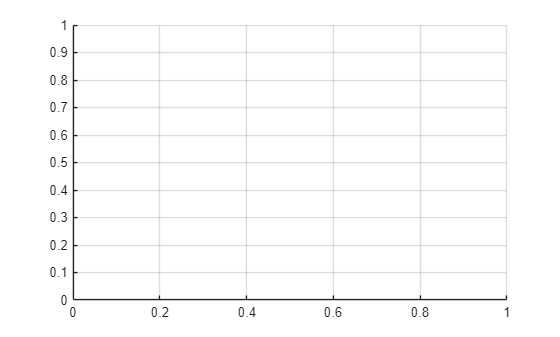

x1 = [];
x2 = [];
soc = linspace(0,1,50);
figure; clf; hold on; grid on;


for k = 1:length(cycles)
    tt = solution(k).T;
    u1 = problem.data.InputCurrent(tt);
    x1(:,k) = speval(solution(k),'X',1,tt);
    x2(:,k) = speval(solution(k),'X',2,tt);
    OCV_SOC = polymodel(problem.data, solution(k).p, soc, 1);
    plot(soc, OCV_SOC, 'LineWidth', 2);
end

Unrecognized function or variable 'cycles'.


xlabel('SOC')
ylabel('OCV')
title('OCV vs SoC')
legend("Cycle count: "+string(cycles), 'Location', 'best');

hold off


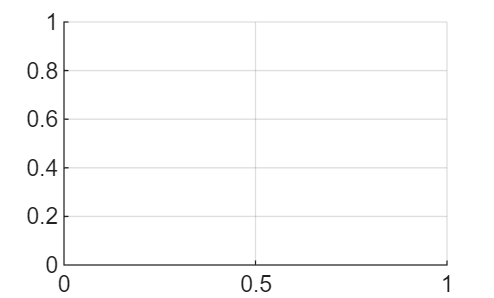

figure; clf; hold on; grid on;


for k = 1:length(cycles)
    plot(solution(k).T, x1(:,k), 'LineWidth', 2)
end

Unrecognized function or variable 'cycles'.


xlabel('Time (s)')
ylabel('SoC')
title('SoC vs Time')

legend("Cycle count: " + string(cycles), 'Location', 'best');
hold off


figure; clf; hold on; grid on;
cap = zeros(length(cycles),1);
for k = 1:length(cycles)
    cap(k) = solution(k).p(problem.data.poly.Q) / 3600;
    plot(k, cap(k), '*', 'MarkerSize', 10);
end
ylabel('Capacity (Ah)')
title('Capacity per Cycle')
legend("Cycle count: "+string(cycles), 'Location', 'best');
hold off


figure; clf; hold on; grid on;
R0 = zeros(cycles,1);
R1 = zeros(cycles,1);
for k = 1:length(cycles)
R0(k) = solution(k).p(problem.data.poly.R0);
R1(k) = solution(k).p(problem.data.poly.R1);
end

hold on
plot(1:k, R0)
plot(1:k, R1)
ylabel('Internal Resistances')
title('Resistance over time')
legend("R0", "R1", 'Location', 'best');
